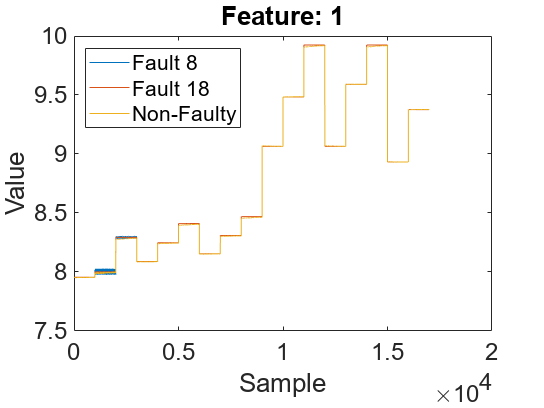

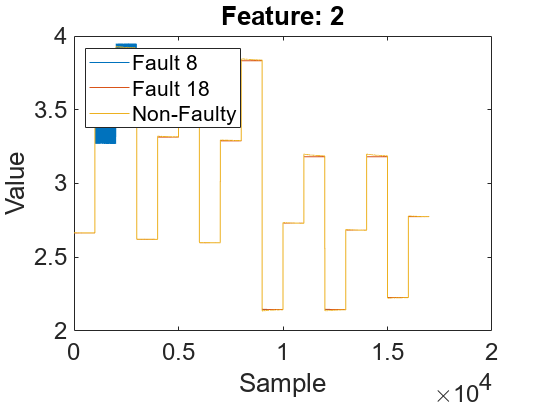

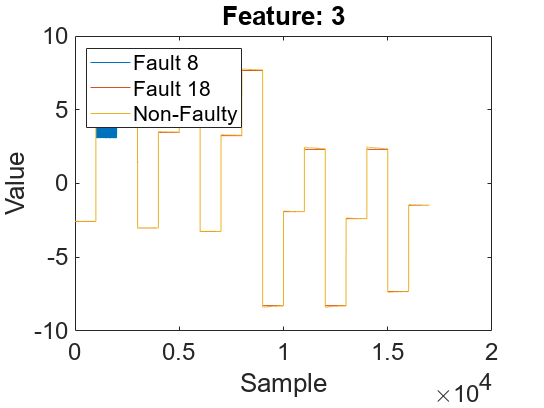

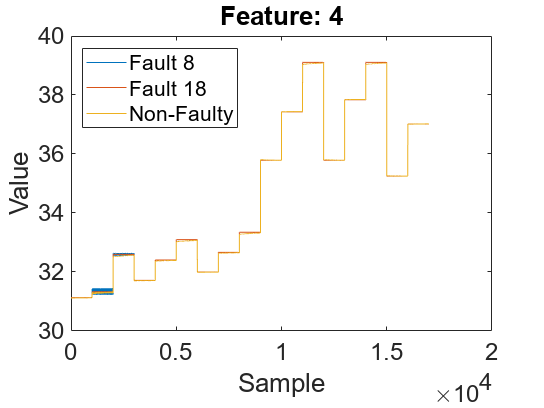

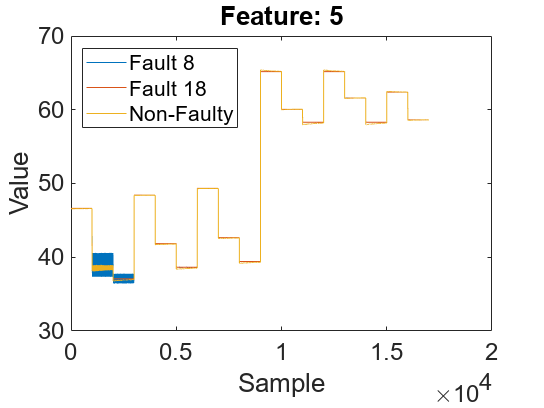

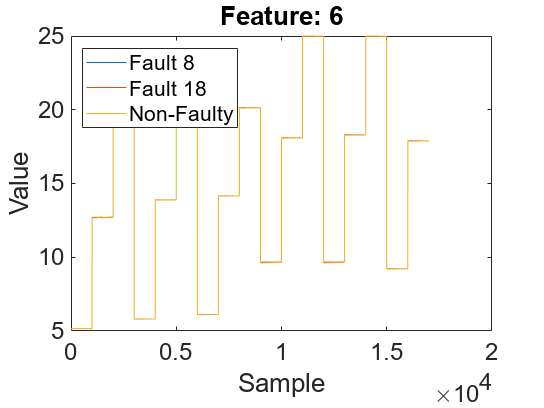

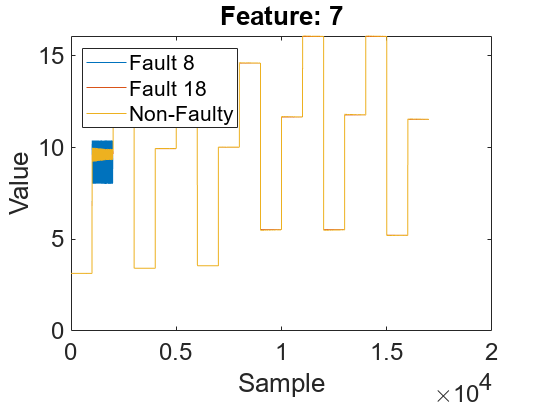

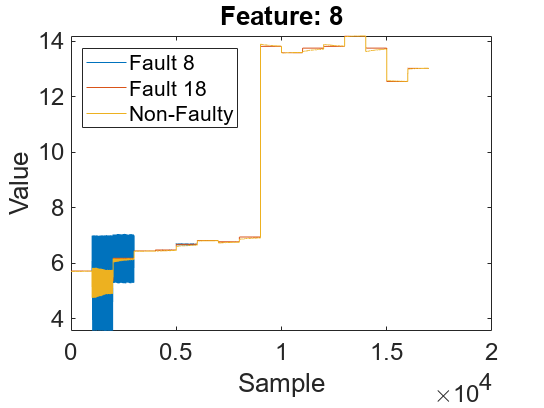

clc
clear
load("MatlabData/trainingDataLoaded.mat")
load("MatlabData/validationDataLoaded.mat")

for i=1:14
    for j=1:17
        SS_8(1000*(j-1)+1:1000*j) = Ftrain8(5001 + (j-1)*6000 : j*6000,i);
        SS_18(1000*(j-1)+1:1000*j) = Ftrain18(5001 + (j-1)*6000 : j*6000,i);
        SS_NF(1000*(j-1)+1:1000*j) = Ntrain1_2(5001 + (j-1)*6000 : j*6000,i);
    end
    figure()
    plot(SS_8)
    hold on
    plot(SS_18)
    plot(SS_NF)
    hold off
    legend("Fault 8", "Fault 18", "Non-Faulty", Location="northwest")
    ylabel("Value")
    xlabel("Sample")
    title(append("Feature: ", num2str(i)))
    set(gca,'FontSize',18)
    saveas(gcf,append("Improvements/Images/FeatureComparison/Feature", num2str(i)),'epsc')
end

Gets the zoomed feature 4

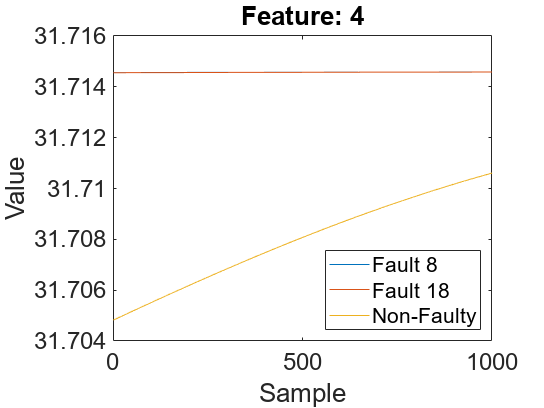

SS_8 = [];
SS_18 = [];
SS_NF = [];
j=4;
SS_8(1:1000) = Ftrain8(5001 + (j-1)*6000 : j*6000,4);
SS_18(1:1000) = Ftrain18(5001 + (j-1)*6000 : j*6000,4);
SS_NF(1:1000) = Ntrain1_2(5001 + (j-1)*6000 : j*6000,4);
figure()
plot(SS_8)
hold on
plot(SS_18)
plot(SS_NF)
hold off
legend("Fault 8", "Fault 18", "Non-Faulty", Location="southeast")
ylabel("Value")
xlabel("Sample")
title("Feature: 4")
set(gca,'FontSize',18)
saveas(gcf,"Improvements/Images/FeatureComparison/Feature4_zoomed",'epsc')

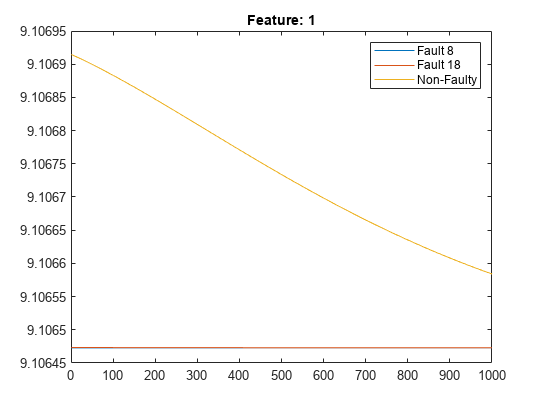

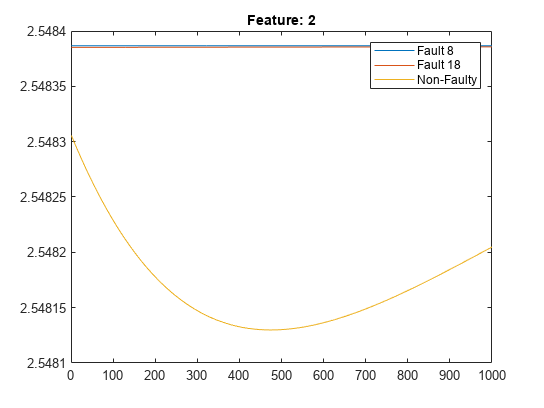

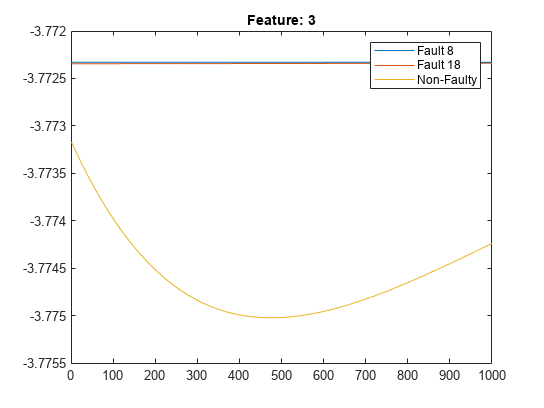

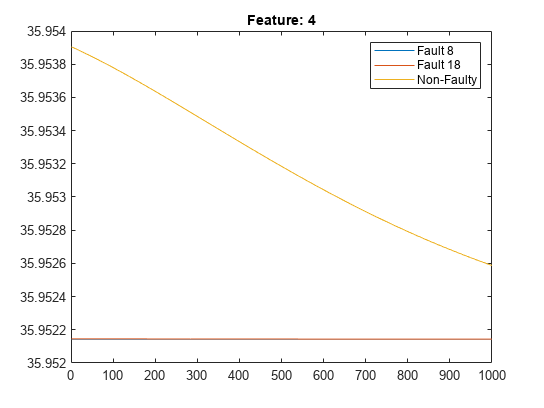

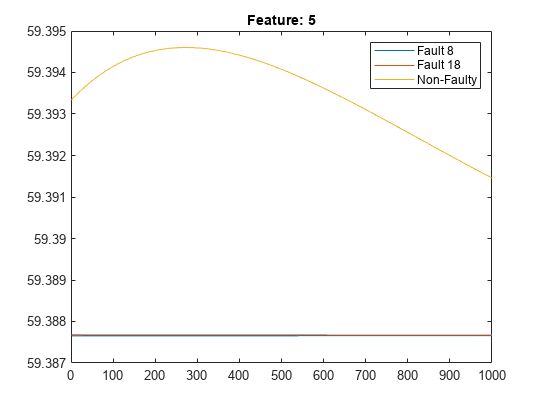

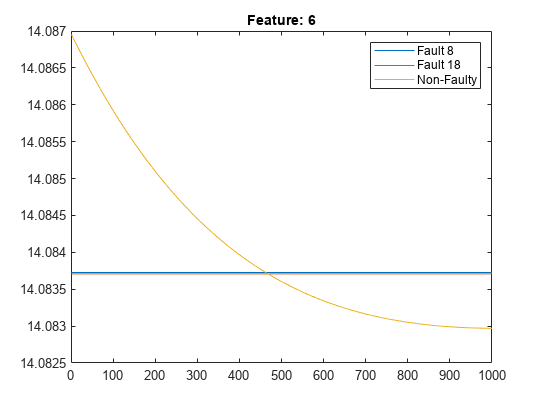

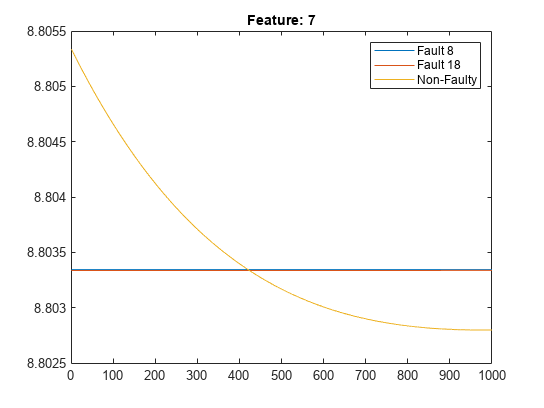

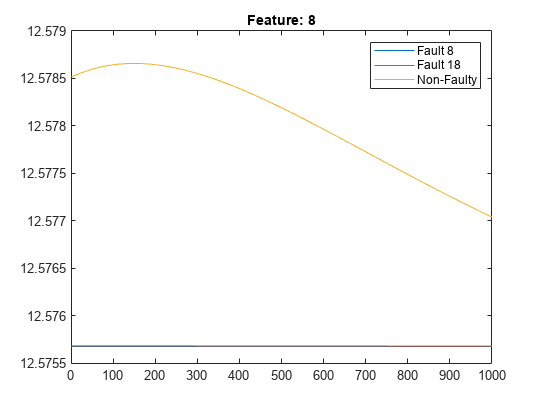


for i=1:14
    figure()
    plot(NewValid_f8(9001:end,i))
    hold on
    plot(NewValid_f18(9001:end,i))
    plot(NewValid_n1_2(5001:end,i))
    hold off
    legend("Fault 8", "Fault 18", "Non-Faulty")
    title(append("Feature: ", num2str(i)))
end

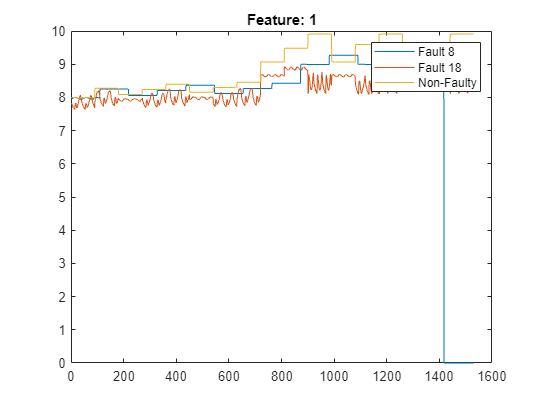

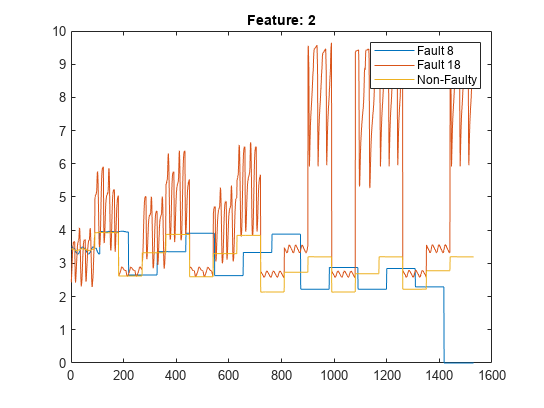

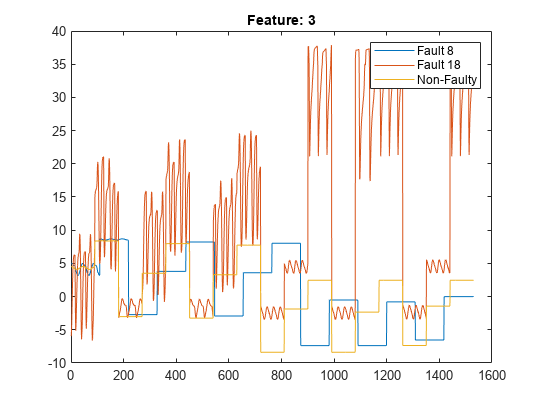

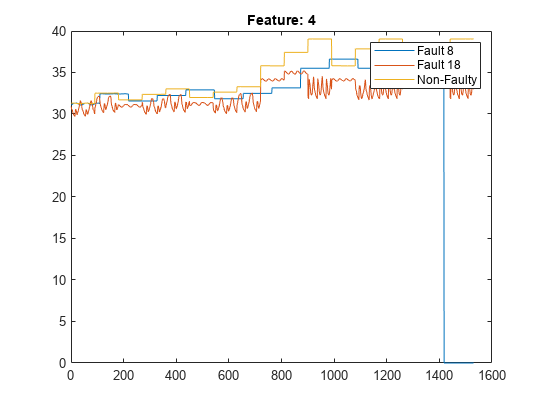

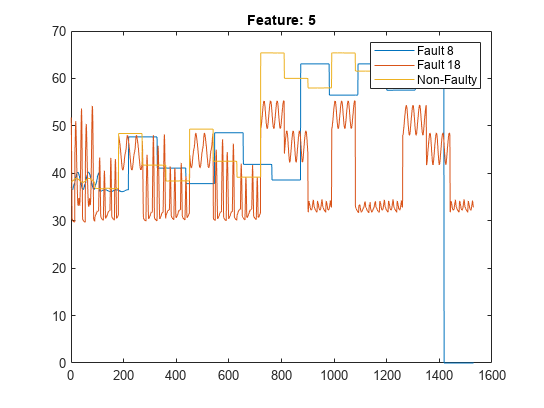

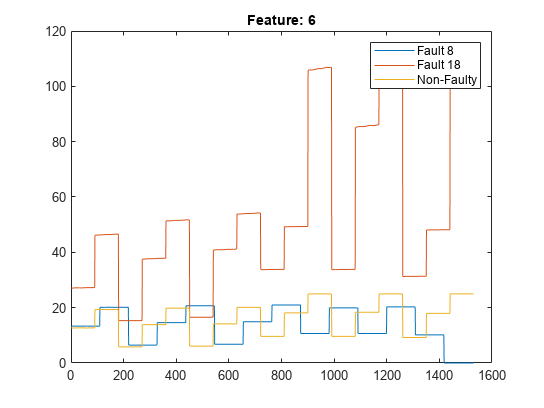

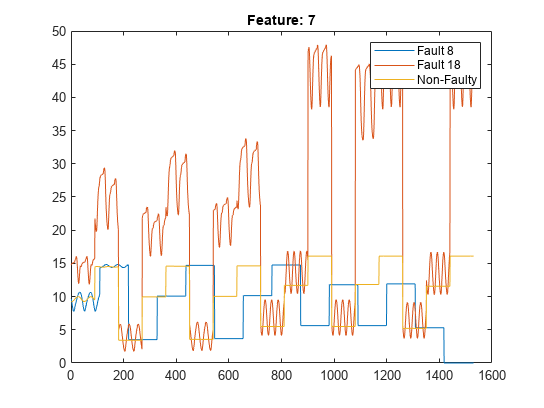

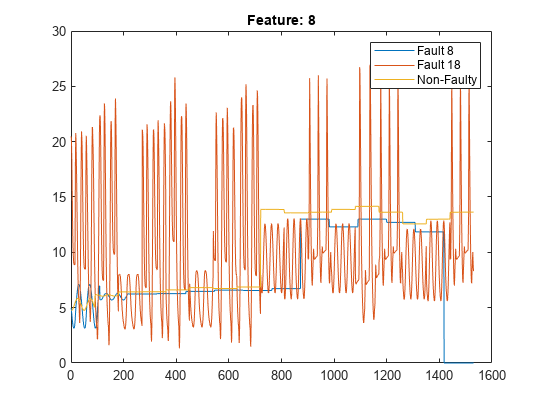

load("MatlabData/trainingData_OG.mat")
n = length(trainingData)/21;
for i=1:14
    figure()
    plot(trainingData(n*8+1:n*9,i))
    hold on
    plot(trainingData(n*18+1:n*19,i))
    plot(trainingData(n*20+1:n*21,i))
    hold off
    legend("Fault 8", "Fault 18", "Non-Faulty")
    title(append("Feature: ", num2str(i)))
end

load("ValidationData_OG_smaller.mat")

Error using load
Unable to find file or directory 'ValidationData_OG_smaller.mat'.

load("trainingData_OG.mat")
W_LDA = LDA_Train(trainingData, trainingLabel,6,80*17);
trainingData_LDA = (W_LDA.' * trainingData.').';
ValidationData_LDA = (W_LDA.' * ValidationData.').';

[normalizedData_LDA,centerValue_LDA,scaleValue_LDA] = normalize(trainingData_LDA,"center",...
    "scale");
trainingData_LDA = normalizedData_LDA;
ValidationData = (ValidationData_LDA - centerValue_LDA) ./ scaleValue_LDA;

for i=1:6
    figure()
    plot(ValidationData(7001:8000,i))
    hold on
    plot(ValidationData(17001:18000,i))
    plot(ValidationData(20001:end,i))
    hold off
    legend("Fault 8", "Fault 18", "Non-Faulty")
    title(append("Feature: ", num2str(i)))
end


function W = LDA_Train(data, label, D, Nk)
    % Calculate mean of each class
    for i=1:21
        mu(i,:)= mean(data(label == i,:));
    end
    % Calculate total mean
    mu(22,:) = mean(data);

    % Calculate within-class scattesr
    Sw = 0;
    for j=1:size(mu,1)-1
        Sw = Sw + (data(find(label==j),:)' - mu(j,:)') * (data(find(label==j),:)' - mu(j,:)')';
    end
    % Calculate between-class scatter
    Sb = Nk .* (mu(1:21,:)' - mu(22,:)') * (mu(1:21,:)' - mu(22,:)')';

    % Use the eigenvalue decomposition and sort it in decending order
    [V e] = eig(Sb,Sw);
    [B,I] = sort(diag(e),'descend');

    % Take D number of eigenvectores corresponding to the largest values
    for i=1:D
        W(:,i) = V(:,I(i));
    end
end